#### **Tasks **

**        A. read an image (*) into a workspace variable.**

**        B. display the image.**

% change directory folder to pick images from
path= 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Input_Images\';

% select Image from using drop down
Selected_Image="peacock.jpg";

% Read and display the image
Input_Image=strcat(path,Selected_Image)

Input_Image = "C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Input_Images\peacock.jpg"

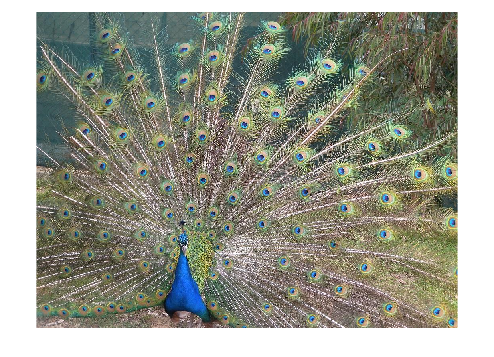

A=imread(Input_Image);
imshow(A)

**        C. apply an image processing filter/effect of your choice (**) to the image.**

**        D. display the result.**

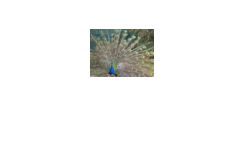

% parameter for blur filter
h = fspecial('motion', 50, 45);

% select effect to be performed on image
effects="imresize(A,0.06)";

% apply the effect and show the new image
B=eval(effects);
imshow(B)

       ** E. save the resulting image to a .png or any other format file.**

% select the desired format for saving the new image
save_format=".jpg";

% Create new file name
[~,name,~] = fileparts(Selected_Image);
newfile=strcat(name,'_new',save_format)

newfile = "peacock_new.jpg"


%change directory to location where image has to be saved
cd 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Output_Images\'

% save image in desired format
imwrite(B,newfile)